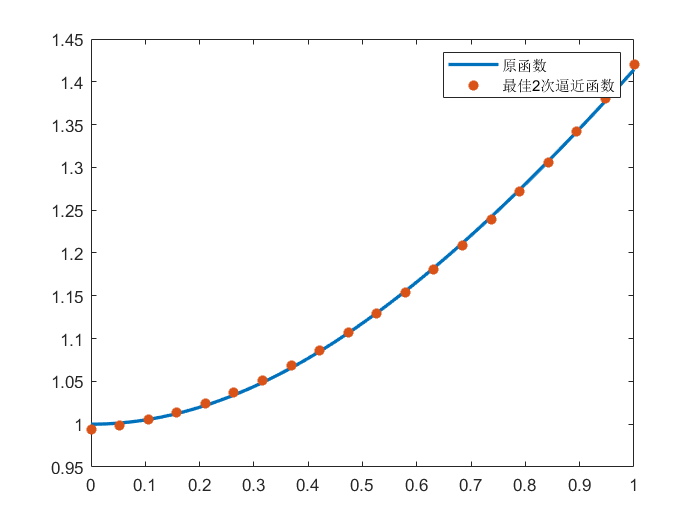

clc,clear,close all
syms x

%------------设置------------%
f = sqrt(1+x^2);   % 逼近函数
n = 2;          % 拟合次数
a = 0;          % 逼近区间
b = 1;          % 逼近区间 [a,b]

%-------------核心代码--------%  
% 算法公式： A*m=b 
% 其中 A 是希尔伯特矩阵，
% b 是 f(x) 与 基函数在0到1做定积分
% m 是基函数前的系数。
% S 逼近函数，是基函数前的系数与基函数做乘积再求和


A = hilb(n+1);              % 希尔伯特矩阵
d = zeros(n+1,1);
for i = 0:n
    f_i = f*x^i;
    d(i+1) = int(f_i,x,0,1);
end
m = A\d;
S = 0;
for i = 0:n
    S = S + m(i+1)*x^i;
end

S = vpa(expand(S),4);

%----------结果输出---------%
% 作图
xx = a:0.01:b;
yy = vpa(subs(f,x,xx));
xx_1 = linspace(a,b,20);
yy_2 = vpa(subs(S,x,xx_1));
plot(xx,yy,xx_1,yy_2,'*','linewidth',2);
legend('原函数',['最佳',num2str(n),'次逼近函数'])

% 输出函数
disp(['最佳',num2str(n),'次逼近函数为'])

最佳2次逼近函数为


disp(S)

$$0.3567\,x^{2}+0.07026\,x+0.9938$$